#     ICE4: Quadratic Transfer Functions with Constant Response Features

#### Locus of Poles for Constant Settling Time

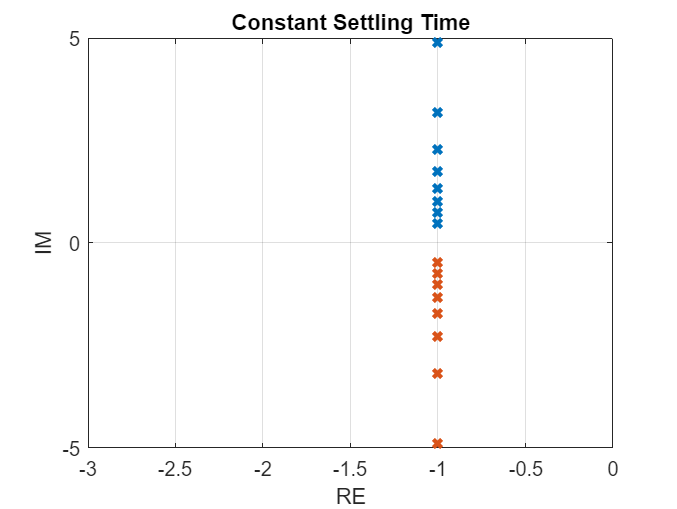

Ts = 4; % fixed settling time
zeta = 0.1:0.1:0.9; % range damping ratio values
itot = length(zeta);

% compute poles at each damping ratio value
for i = 1:itot 
    omega_n = 4 / (Ts*zeta(i)); % compute natural frequency
    num = 1; % numerator quadratic transfer function
    den = [1 2*zeta(i)*omega_n omega_n*omega_n]; % denominator
    DYN = tf(num, den); % transfer function object
    p = pole(DYN); % compute poles
    pcomplex(i,:) = p; % store complex poles
end

% plot
plot(pcomplex,'x','LineWidth',2); 
grid
axis([-3 0 -5 5]) % range of RE and IM axes
title("Constant Settling Time")
xlabel('RE')
ylabel('IM')

#### Locus of Poles for Constant Peak Time

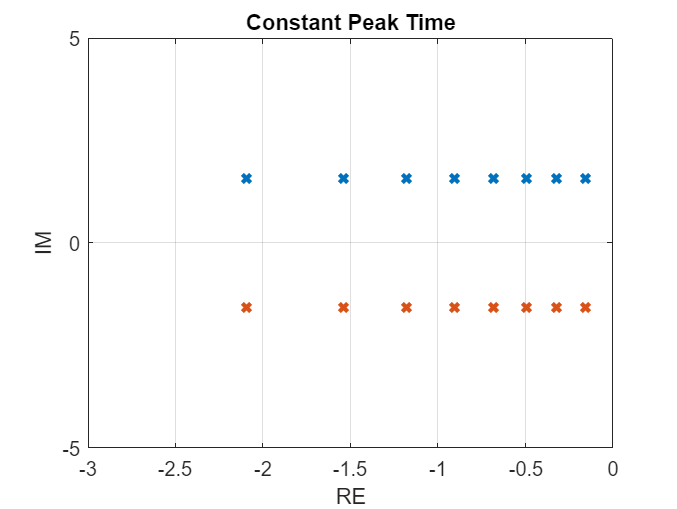

Tp = 2; % fixed peak time
zeta = 0.1:0.1:0.9; % range damping ratio values
itot = length(zeta);

% compute poles at each damping ratio value
for i = 1:itot 
    omega_n = pi / (Tp * sqrt(1-zeta(i)^2)); % compute natural frequency
    num = 1; % numerator quadratic transfer function
    den = [1 2*zeta(i)*omega_n omega_n*omega_n]; % denominator
    DYN = tf(num, den); % transfer function object
    p = pole(DYN); % compute poles
    pcomplex(i,:) = p; % store complex poles
end

% plot
plot(pcomplex,'x','LineWidth',2); 
grid
axis([-3 0 -5 5]) % range of RE and IM axes
title("Constant Peak Time")
xlabel('RE')
ylabel('IM')

#### Locus of Poles for Constant Percent Overshoot

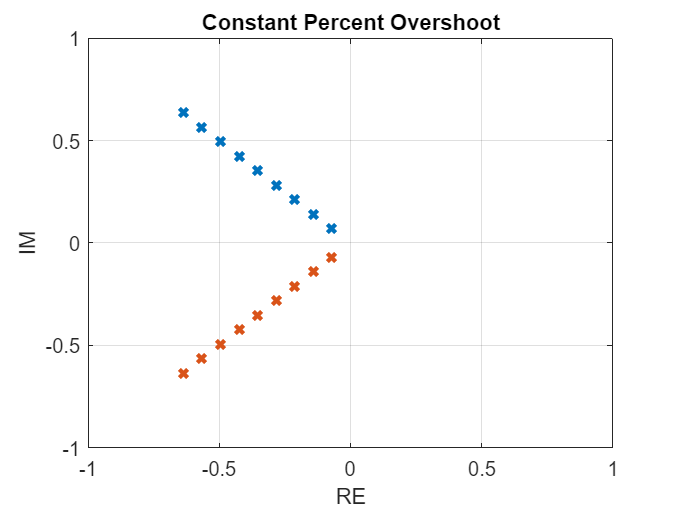

zeta = 0.707143; % fixed damping ratio
omega_n = 0.1:0.1:0.9; % range natural frequency values
itot = length(omega_n);

% compute poles at each damping ratio value
for i = 1:itot 
    num = 1; % numerator quadratic transfer function
    den = [1 2*zeta*omega_n(i) omega_n(i)*omega_n(i)]; % denominator
    DYN = tf(num, den); % transfer function object
    p = pole(DYN); % compute poles
    pcomplex(i,:) = p; % store complex poles
end

% plot
plot(pcomplex,'x','LineWidth',2); 
grid
axis([-1 1 -1 1]) % range of RE and IM axes
title("Constant Percent Overshoot")
xlabel('RE')
ylabel('IM')

#### Locus of Poles for Constant Natural Frequency

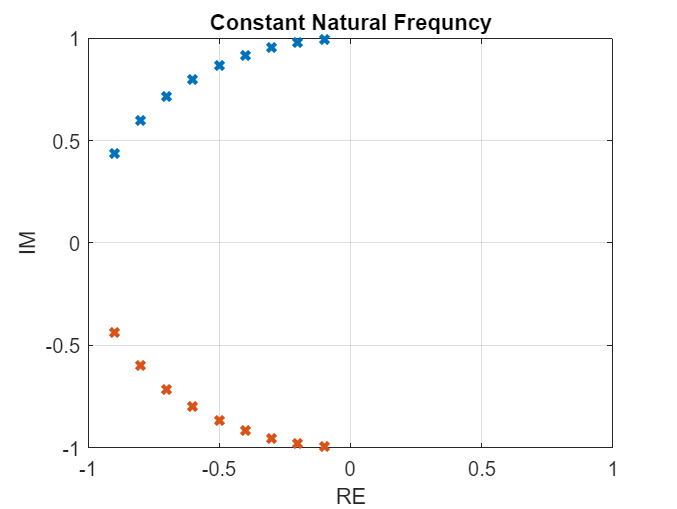

omega_n = 1; % fixed natural frequency
zeta = 0.1:0.1:0.9; % range damping ratio values
itot = length(zeta);

% compute poles at each damping ratio value
for i = 1:itot 
    num = 1; % numerator quadratic transfer function
    den = [1 2*zeta(i)*omega_n omega_n*omega_n]; % denominator
    DYN = tf(num, den); % transfer function object
    p = pole(DYN); % compute poles
    pcomplex(i,:) = p; % store complex poles
end

% plot
plot(pcomplex,'x','LineWidth',2); 
grid
axis([-1 1 -1 1]) % range of RE and IM axes
title("Constant Natural Frequncy")
xlabel('RE')
ylabel('IM')